# **Addressing Target Loss and Actuator Saturation in Visual Servoing of Multi-rotors: A Non-recursive Augmented Dynamics Control Approach**

### **Archit Krishna Kamath and Mir Feroskhan**

## **Numerical Simulation Example:**

To demonstrate the effectiveness of the controller, consider the nonlinear second order system:


$$
\dot{x}_1 = x_2  \\
\dot{x}_2 = \sin(x_1)+x_2+u+d$$


where $f(x_1,x_2) = \sin(x_1)+x_2$ and $g(x_1,x_2) = 1$. The above system is subjected to the input and state constraints $\mathcal{X}$, as shown below:


$$\mathcal{X} = \left\{ 
   \begin{array}{@{}l@{}}
   -1 < x_1 < 1 \\ 
   -1 < x_2 < 1 \\
   -8 \leq u \leq 8 
   \end{array}
\right\}$$


#### Initialization:

clc; clear all; close all;

#### Constraints:

U = 8; 
x1_max = 1; x1_min = -1; 
x2_max = 1; x2_min = -1; 

#### System Initial Conditions and Iteration Time:

x11 = 0.9; x21 = 0.9; 
xd = 0.1; xdd = 0; xddd = 0; 
t0 = 0; dt = 0.01; itn = 600; 

## Controller Description:

Consider the control effort $u(t)$ as:


$$u = \begin{cases} 
      -U & \mathcal{S}_1 \cup \mathcal{S}_2 \cup \mathcal{S}_3 \\
      U & \mathcal{S}_4 \cup \mathcal{S}_5 \cup \mathcal{S}_6 \\
      \mu & \text{else} 
   \end{cases}$$


where $\mu \in \mathbb{R}$ is derived using a terminal sliding mode control strategy with a power rate reaching law and is given as:


$$\mu = -g^{-1}\left[f+\frac{\lambda}{\gamma}|x_2|^{2-\gamma}sign(x_2)+K|S|^\alpha sign(S) \right] $$


where, $S =  |x_2|^{\gamma}sign(x_2)+\lambda x_1$. The controller parameters are tuned such that $-U \leq \mu \leq U \ \forall  \ t >0$. The sets $\mathcal{S}_{1-6}$ are defined as:


$$\mathcal{S}_1=   \left[(x_1,x_2) : x_2 \geq x_{2_{max}} \ \text{and} \  x_1 > x_{1_{min}}\right] \\
\mathcal{S}_2 = \left[(x_1,x_2) : x_1 \geq -\frac{|x_2|^\gamma}{\lambda}+x_{1_{max}}  \ \text{and} \ x_2>0   \right] \\
\mathcal{S}_3 =  \left[(x_1,x_2) : x_1 \geq x_{1_{max}} \ \text{and} \ x_2\leq0 \right] \\
\mathcal{S}_4 =   \left[(x_1,x_2) : x_2 \leq x_{2_{max}} \ \text{and} \  x_1 < x_{1_{max}} \right] \\
\mathcal{S}_5 =  \left[(x_1,x_2) : x_1 \leq \frac{|x_2|^\gamma}{\lambda}+x_{1_{max}}  \ \text{and} \ x_2<0   \right] \\
\mathcal{S}_6 =  \left[(x_1,x_2) : x_1 \leq x_{1_{max}} \ \text{and} \ x_2\geq0 \right]$$


where $\gamma \in \mathbb{R}^+$ and $\lambda \in \mathbb{R}^+$ are surface parameters such that $1<\gamma = m/n<2$ and $m$ and $n$ are odd numbers. This controller is compared with the work presented in [1]. The function 'constrain_control_reg' presents the proposed controller and the function 'constrain_control_reg_compare' represents the strategy presented in [1]. The function 'performance_index' is used to obtain the the perfromance indices i.e. ISE, IAE, ITAE, ACE, $\Delta_u$, DOC for the two cases.

#### Control Parameters:

L = 0.65; gamma = 59/53; alpha = 0.85; D_max = 0.02;

#### Implementation:

x10 = x11; x20 = x21;
[x1,x2,u,K,t] = constrain_control_reg(U,x1_max,x1_min,x2_max, ...
    x2_min,x10,x20,L,gamma,alpha,xd,xdd,xddd,dt,itn,t0,D_max);
[x1_comp,x2_comp,u_comp,t] = constrain_control_reg_compare(U, ...
    x2_max,x2_min,x10,x20,L,xd,xdd,xddd,dt,itn,t0,D_max);
Y = [x1' x2']; M = [u']; Y_comp = [x1_comp' x2_comp']; M_comp = [u_comp'];
[ISE,IAE,ITAE,ACE,DELU,DOC] = performance_index(Y,M,t,dt);
[ISE_comp,IAE_comp,ITAE_comp,ACE_comp,...
    DELU_comp,DOC_comp] =performance_index(Y_comp,M_comp,t,dt);

#### Plot State Trajactories:

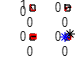

figure(1)
subplot(2,2,1);
plot(t(1:itn),x1(1:itn), 'k');
hold on;
plot(t(1:itn),x1_comp(1:itn), 'r');
hold on;
grid on;
subplot(2,2,2);
plot(t(1:itn),x2_comp(1:itn), 'r');
hold on;
plot(t(1:itn),x2(1:itn), 'k');
hold on;
grid on;
subplot(2,2,3);
plot(t(1:itn),u_comp, 'r');
hold on;
plot(t(1:itn),u, 'k');
hold on;
grid on;
subplot(2,2,4);
plot(x1(1:itn),x2(1:itn), 'k');
hold on;
plot(x1_comp(1:itn),x2_comp(1:itn), 'r');
hold on;
scatter(x10,x20,'k*');
hold on;
grid on;
subplot(2,2,4);
scatter(xd,xdd,'b*');
hold off;

function [ISE,IAE,ITAE,ACE,DELU,DOC] = performance_index(X,U,t,dt)
    [row_x,col_x] = size(X);
    [row_u,col_u] = size(U);
    ex = zeros(row_x,1); eu = zeros(row_u,1);
    for i=1:col_x
        ex = ex+X(:,i);
    end
    for j=1:col_u
        eu = eu+U(:,j);
    end
    t = t';
    ISE = trapz(t,(abs(ex)).^2); 
    IAE = trapz(t,abs(ex));
    ITAE = trapz(t,t.*abs(ex));
    
    Integ = trapz(t(1:length(eu)),abs(eu));
    ACE = sqrt(Integ/(dt*length(eu)));
    
    del_u(1) = abs(eu(1))^2;
    for k=2:length(eu)
        del_u(k) = (abs(eu(k)-eu(k-1)))^2;
    end
    DELU = (sum(del_u)/length(eu))^0.5;
    DOC = DELU/ACE;
end
function [x1,x2,u,t] = constrain_control_reg_compare(U,x2_max,...
    x2_min,x11,x21,L,xd,xdd,xddd,dt,itn,t1,D_max)
    x1(1) = x11; x2(1) = x21; t(1) = t1; 
    e2_max = x2_max-max(abs(xdd)); e2_min = x2_min-max(abs(xdd)); 
    xd_max = max(abs(xd)); xdd_max = max(abs(xdd)); xddd_max = max(abs(xddd));
    for i = 1:itn
        e1 = x1(i)-xd; e2 = x2(i)-xdd;
        u(i) = control(U,L,e2_max,e2_min,e1,e2);
        d(i) = D_max*sin(0.1*i*dt);
        x1(i+1) = x1(i)+dt*x2(i);
        x2(i+1) = x2(i)+(dt)*(sin(x1(i))+x2(i)+u(i)+d(i));
        t(i+1) = t(i)+dt;
    end
end
function u = control(U,U1,e2_max,e2_min,e1,e2)
    if (e2>=e2_max)||((e1 == -e2*abs(e2)/(2*U1)) && e2>0)...
            ||(e2<=e2_max && (e1>-e2*abs(e2)/(2*U1)))
        u = -U;
    elseif (e2<=e2_min)||((e1 == -e2*abs(e2)/(2*U1)) && e2<0)...
            ||(e2>=e2_min && (e1<-e2*abs(e2)/(2*U1)))
        u = U;
    else
        u = 0;
    end
end
function [x1,x2,u,K,t] = constrain_control_reg(U,x1_max,...
    x1_min,x2_max,x2_min,x11,x21,L,gamma,alpha,xd,xdd,xddd,dt,itn,t1,D_max)
    x1(1) = x11; x2(1) = x21; t(1) = t1;
    e1_max = x1_max-max(abs(xd)); e1_min = x1_min-max(abs(xd)); 
    e2_max = x2_max-max(abs(xdd)); e2_min = x2_min-max(abs(xdd)); 
    xd_max = max(abs(xd)); xdd_max = max(abs(xdd)); xddd_max = max(abs(xddd));
    for i = 1:itn
        e1 = x1(i)-xd; e2 = x2(i)-xdd;
        [u(i),K(i)] = control1(U,e1_max,e1_min,e2_max,e2_min,e1,e2,L,...
            gamma,alpha,xd,xdd,xddd,xd_max,xdd_max,xddd_max);
        d(i) = D_max*sin(0.1*i*dt);
        x1(i+1) = x1(i)+dt*x2(i);
        x2(i+1) = x2(i)+(dt)*(sin(x1(i))+x2(i)+u(i)+d(i));
        t(i+1) = t(i)+dt;
    end
end
function [u,K] = control1(U,e1_max,e1_min,e2_max,e2_min,e1,e2,...
    L,gamma,alpha,xd,xdd,xddd,xd_max,xdd_max,xddd_max)
    if (e2>=e2_max && e1>e1_min)||((e1 >= -((1/L)*(e2^gamma))+e1_max)...
            && e2>0)|| (e1>=e1_max && e2<=0)
        K = 0;
        u = -U;
    elseif (e2<=e2_min && e1<e1_max)||((e1 <= ((1/L)*(abs(e2)^gamma))+e1_min)...
            && e2<0) || (e1<=e1_min && e2>=0)
        K = 0;
        u = U;
    else
        S_max = max(abs(e2_max),abs(e2_min))^gamma+L*max(abs(e1_max),abs(e1_min));
        F_max = sin(max(abs(e1_max+xd_max),abs(e1_min+xd_max)))...
            +max(abs(e2_max+xdd_max),abs(e2_min+xdd_max));
        G_max = max(abs(e2_max),abs(e2_min));
        K = ((U-xddd_max-F_max-(L/gamma)*(G_max^(2-gamma)))/...
            ((S_max)^alpha))-0.1;
        S = (abs(e2)^gamma)*sign(e2)+L*(e1);
        S_dot = -K*(abs(S)^alpha)*sign(S);    
        u = xddd-(sin(e1+xd)+e2+xdd)+(L/gamma)*(abs(e2)^(2-gamma))...
            *sign(e2)+(S_dot);
    end
end